**1. Example**

1.1 Problem: estimate $\left(a,b\right)$ with sampled points at $t_{i\;}$


$$f =ab/(b+t) $$


 1.2 Generate Data

For study Newton- gauss non-linear LME, we need measurements in real situation, but here we generate a data with $\left(a,b\right)=\left(1,2\right)$

clear all;clc
a = 1; b= 2;
Data =[ ]


Data =

     []



for i = 1:3
    Data(i,:) =[i, a*b/(b+i)];
end
Data

Data =     1.0000    0.6667
    2.0000    0.5000
    3.0000    0.4000



syms a b t 
f = a*b/(b+t);

% generate Jacobian matrix

H = [diff(f,a)  diff(f,b)];  % gradient w.r.t the estimators
estX =[2;10];                 % initial guess of estimators
Z =[ ];
JA = [ ];
for k = 1:10
    for i = 1:3
        Z=[Z; Data(i,2) - subs(f,[a,b,t],[estX(1), estX(2), Data(i,1)])];
        JA =[JA;subs(H,[a,b,t],[estX(1), estX(2),Data(i,1)])];
    end     
    
  PseJA = inv(JA'*JA)*JA';   % pseudo Inverse
  estX =estX +PseJA*Z;       % next estimator
  estX = double(estX)        % conver to double
  Z=[ ];
  JA =[ ];
 end

estX =    Inf
   Inf


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


estX =    NaN
   NaN


 estX 

estX =    NaN
   NaN


here we get the real value at the frist step. If you change the initial guess 

**2. Example**

https://en.wikipedia.org/wiki/Gauss%E2%80%93Newton_algorithm

1. problem 

In biology an example, the measurement is the rate $R$, function of the concentration, $S$


$$R = \frac{aS}_{b+S}, 

$$


to estiamte $a ,\ b$ with the measurement as 

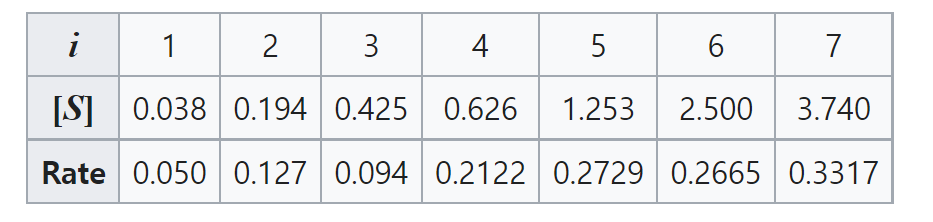

Here is the non-linear w.r.t the variable $S$ and the estimators

2. Procesure

2.1 Data generation

clear all; clc
% Data 
DataS =[0.038;0.194;0.425;0.626;1.253;2.500;...
        3.740];
DataR = [0.050;0.127;0.094;0.2122;0.2729;0.2665;...
        0.3317];   
Data=[DataS DataR]

Data =     0.0380    0.0500
    0.1940    0.1270
    0.4250    0.0940
    0.6260    0.2122
    1.2530    0.2729
    2.5000    0.2665
    3.7400    0.3317


plot(Data(:,1), Data(:,2),'ro');grid on;hold on

syms a b S
R = a*S/(b + S);
% Gradient 
H = [diff(R,a) diff(R,b)];
% calculate the error with the first estimator
estX =[0.9;0.2];
Z =[ ];
JA = [ ];
for k = 1:10
    for i = 1:7
        Z=[Z; Data(i,2) - subs(R,[a,b,S],[estX(1), estX(2), Data(i,1)])];
        JA =[JA;subs(H,[a,b,S],[estX(1), estX(2),Data(i,1)])];     
    end 
  PseJA = inv(JA'*JA)*JA';  
  estX =estX +PseJA*Z;
  estX = double(estX);
  Z = [ ];    % generate the next error
  JA =[ ];    % generate the next Jacobian
end
estX

estX =     0.3618
    0.5563



% plot of the estimator output

x = linspace(0,4,100)

x =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798


temp =estX(1).*x./(estX(2)+ x)

temp =          0    0.0245    0.0459    0.0647    0.0815    0.0964    0.1098    0.1220    0.1330    0.1430    0.1522    0.1607    0.1685    0.1757    0.1824    0.1887    0.1945    0.1999    0.2050    0.2098    0.2143    0.2186    0.2226    0.2263    0.2299    0.2333    0.2366    0.2396    0.2426    0.2454    0.2480    0.2506    0.2530    0.2553    0.2575    0.2597    0.2617    0.2637    0.2656    0.2674    0.2692    0.2709    0.2725    0.2741    0.2756    0.2771    0.2785    0.2799    0.2812    0.2825


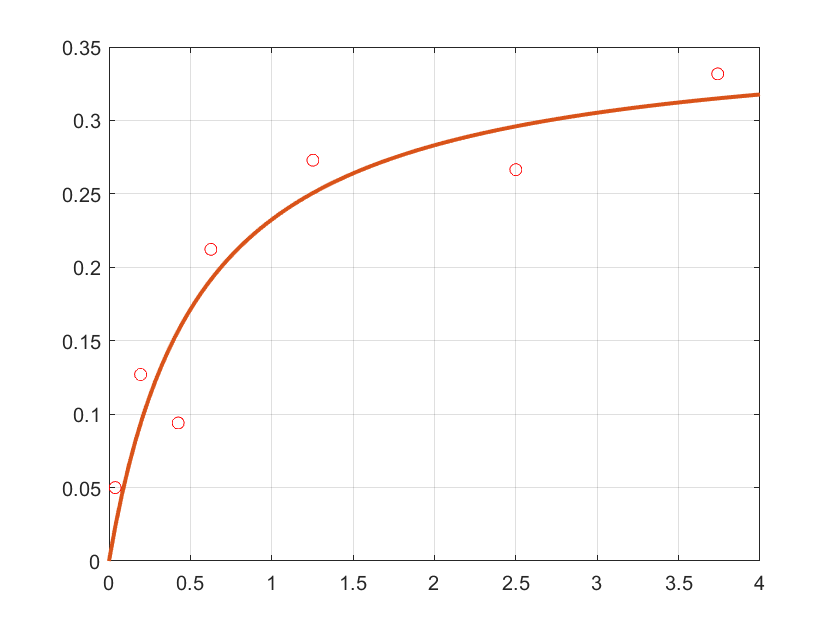

plot(x,temp,'linewidth',2); hold off

Ex. 4.8 Gauss Data

 
$$r=\frac{a}{\left(1+e\;\cos \;\left(\theta -\theta {\;}_p \right)\right)}$$


 given data $\left(r_{i\;} ,\theta {\;}_{i\;} \right)\;,i=1,2,3\;$ estiamte $a,e,\theta \;$

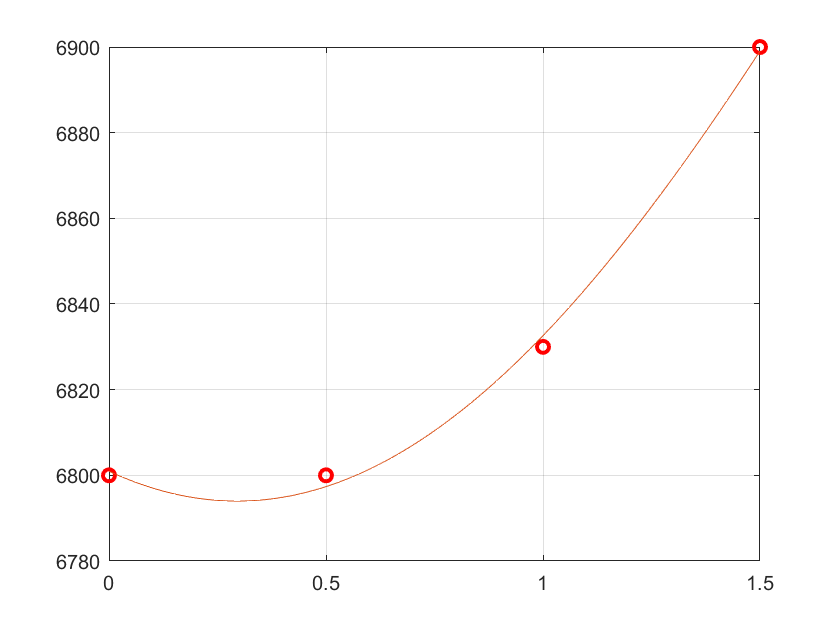

%% Ex. 4.8 Gauss Data
clear all; clc
LW = 'linewidth';
% Data 
DataR =[6800; 6800;6830; 6900];
DataS = [0; 0.5; 1.0; 1.5];
Data =[DataS DataR];
figure(1)
plot(Data(:,1),Data(:,2),'ro', LW,2);grid on;hold on


syms a e th thP
R = a/(1+e*cos(th-thP));
% Gradient 
H = [diff(R,a) diff(R,e)  diff(R,thP)];

% calculate the error with the first estimator
estX =[6900;0.02;0.01];  %[a e thP]
Z =[ ];
JA = [ ];
for k = 1:4
    for i = 1:4
        Z=[Z; Data(i,2) - subs(R,[a,e,thP,th],[estX(1), estX(2),estX(3) Data(i,1)])];
        JA =[JA;subs(H, [a,e,thP,th],[estX(1), estX(2),estX(3),Data(i,1)])];     
    end 
  JA = double(JA);
  PseJA = inv(JA'*JA)*JA';  
  estX =estX +PseJA*Z;
  estX = double(estX);
  Z = [ ];
  JA =[ ];
end
  
  %
  a = estX(1);
  e= estX(2);
  thP = estX(3);
  
  th= linspace(0,1.5, 100);
  estX = a./(1+e.*cos(th-thP));
  
  plot(th,estX) 